## Tutorial on the modulating pattern and the downsampling process

**Recap from last week:**

Get the general settings (data path, source code path, generated report path)

run("../CIRLSetup.m")

HR settings of a 200x200x200 Bead for the 3-slit Tunable system

[ psfpar, psfpari ] = PSFConfigNoAber();
X     = 200;                        % discrete lateral size in voxels
Y     = 200;                        % discrete lateral size in voxels
Z     = 200;                        % discrete axial size in voxels
dXY   = 0.05;                      % lateral voxel scaling in microns ---- for 20X lens (6.4/20)....for 60X lens (6.4/63)
dZ    = 0.05;                      % axial voxel scaling in microns
uc    = 2*psfpar.NA/psfpari.v(1);   % cycle/um
offs  = [0, 0, 0];                  % offset from the standard values of phi
phi   = [0, 1, 2]*(2*180)/3;        % lateral phase
theta = [0, 60, 120];               % orientation
um    = [0.8, 0.8, 0.8]*uc;         % lateral modulating frequency
x0    = 0.326;  % in mm
fL1   = 100;    % in mm
fL2   = 250;    % in mm
fMO   = 160/63;
wm    = ((x0*fL2)/(2*fL1*fMO))*um;  % axial modulating frequency
phizDeg   = 46.0;                   % axial phase
Nslits    = 3;

HR point spread function

h  = PSFAgard( X, Z, dXY, dZ);

HR modulating pattern

[im, jm, ~] = PatternTunable3DNSlits(X, Y, Z, um, wm, dXY, dZ, phi, offs, theta, phizDeg, Nslits);

HR bead object construction

Radius    = 4/2;
Thickness = 2/2;
ob        = SphericalShell(X, Y, Z, dXY, Radius, Thickness);

HR forward images

gHR  = ForwardModel(ob, h, im, jm);

**This week:**

1. Get the size of the forward image:

[X, Y, Z, ~, ~] = size(gHR)

X = 200

Y = 200

Z = 200

List the orientations:

theta

theta =      0    60   120


List the phases:

phi

phi =      0   120   240


2. Get the forward image of the orientation 60 and the phase 0:

gHR_60_0 = gHR(:,:,:,2,1);

3. Plot the forward image g_60_0 above:

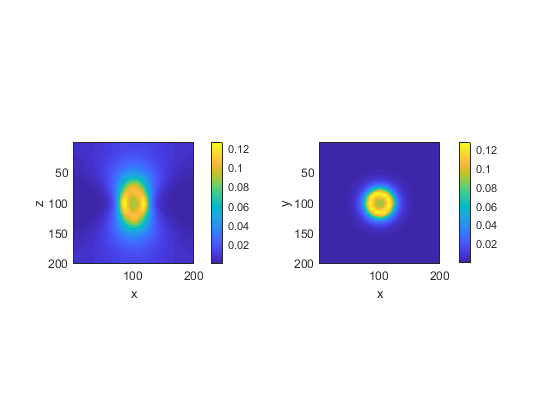

figure;
subplot(1,2,1); imagesc(squeeze(gHR_60_0(1+Y/2,:,:))');
axis square; xlabel('x'); ylabel('z'); colorbar; 
subplot(1,2,2); imagesc(gHR_60_0(:,:,1 + Z/2));
axis square; xlabel('x'); ylabel('y'); colorbar; 

4. Downsampling the forward image g_60_0 by taking the **odd indeces**:

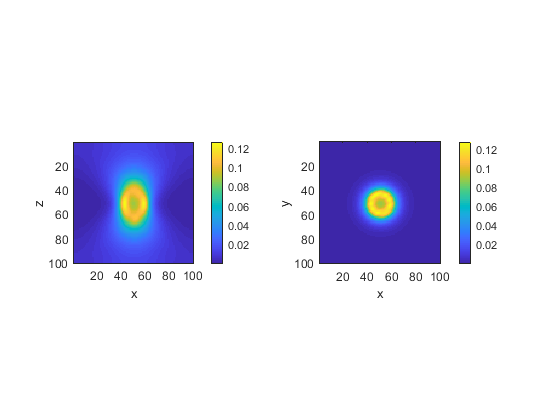

gOdd_60_0 = gHR_60_0(1:2:end, 1:2:end, 1:2:end);
halfZ = Z/2;
halfX = X/2;
figure;
subplot(1,2,1); imagesc(squeeze(gOdd_60_0(1 + halfX/2,:,:))');
axis square; xlabel('x'); ylabel('z'); colorbar; 
subplot(1,2,2); imagesc(gOdd_60_0(:,:,1 + halfZ/2));
axis square; xlabel('x'); ylabel('y'); colorbar; 

5. (**question**) What are the differences between the 2 pictures above in 3 and 4?

Answer: ...

6. (**exercises**) Please do the downsampling of the forward image g_60_0 by taking the **even indeces** and plot xy, xz pictures for it.

gEven_60_0 = ...
figure;
...

Is there any difference between the picture in 4. and this picture?

Answer: ...

7. Save the downsampled data to CIRLDataPath:

g = gHR(1:2:end, 1:2:end, 1:2:end, :, :);
matFile = CIRLDataPath + "\Simulation\Tunable\SimTunableBead100.mat";
save(matFile, 'g');

**More on the modulating patterns:**

8. Plotting the lateral pattern of the orientation 60 and the phase 0 (second component):

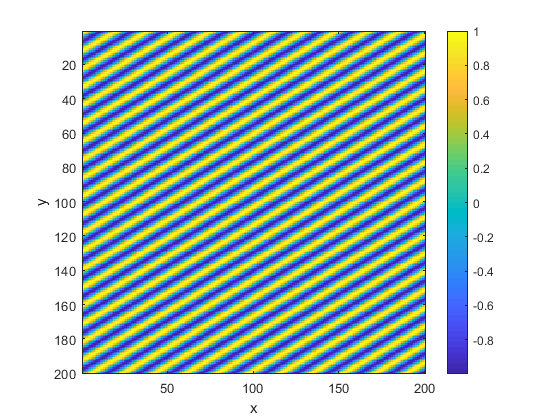

jm_60_0_2 = jm(:,:,:,2,1,2);
figure;
imagesc(jm_60_0_2(:,:,1+Z/2)); axis square; xlabel('x'); ylabel('y'); colorbar; 

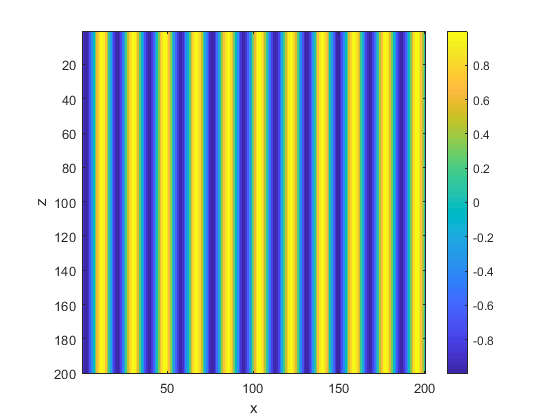

imagesc(squeeze(jm_60_0_2(1+Y/2,:,:))'); axis square; xlabel('x'); ylabel('z'); colorbar; 

9. (**question**) In the formula of the forward model, it says that jm only depends on x, y and does not depend on z. Do the pictures above agree with the formula?

Answer: ...

10. (**exercises**) Similarly to questions 8 and 9: plot the axial pattern of the orientation 60 and the phase 0 (second component).  In the formula of the forward model, it says that im only depends on z and does not depend on x and y. Do the pictures above agree with the formula?

im_60_0_2 = ...
figure;
...
figure;
...